%{
Name: Cart Speed Profile
Author: Evan Scheuritzel
Version: 1.0
Purpose: analyze how a carts speed can be turned into more valuable data
Input: none
Output: Speed & Accleration plots + max speed timing
%}

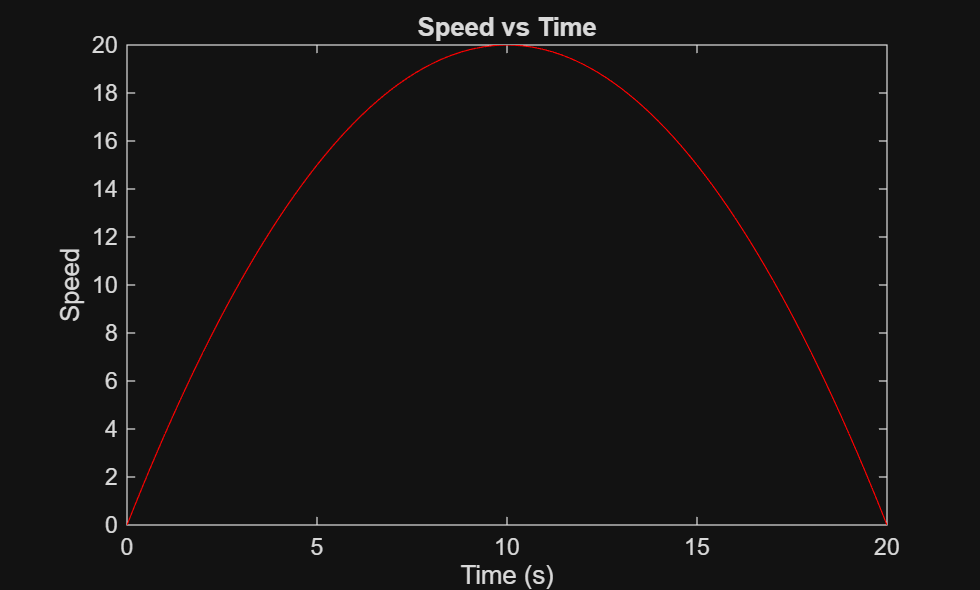

clear
t = 0:0.2:20;
v = -0.2*(t-10).^2+20;
plot(t,v,'red')
title('Speed vs Time')
xlabel('Time (s)')
ylabel('Speed')

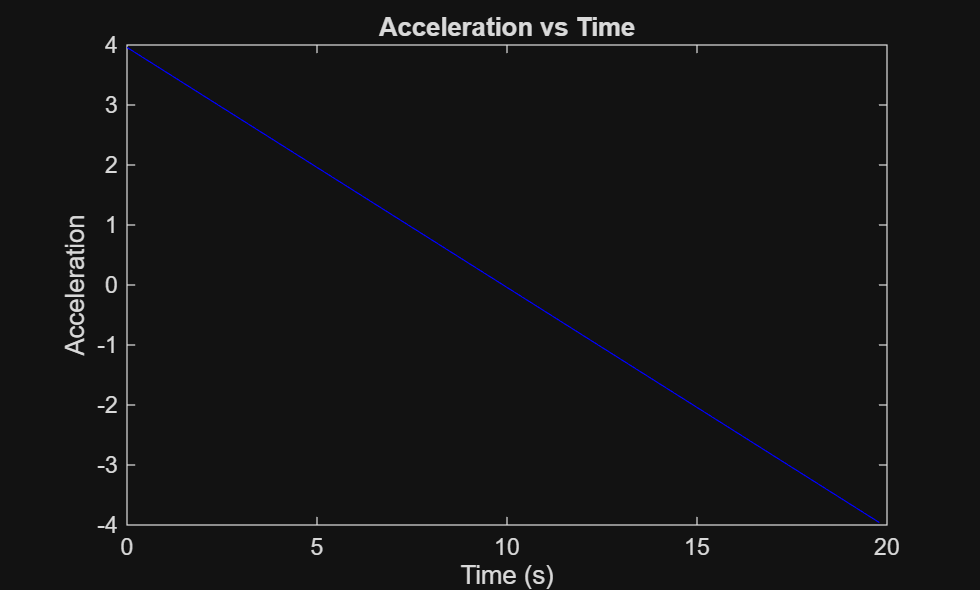

a = diff(v)./diff(t);
plot(t(1:length(a)),a,'blue')
title('Acceleration vs Time')
xlabel('Time (s)')
ylabel('Acceleration')

i = (v == max(v));
l = "Max speed at "+ t(i) +"s Accleration is " + a(i);
disp(l)

Max speed at 10s Accleration is -0.04


%1. vertex is the peak of speed, it also happens to be just as speed starts
%to decrease
%2. the accleration estimation being on a negative trend means that there
%is a increasing force slowing the cart down.